# **OFDM Receiver Testing Without Channel coding**

This example shows how to design an orthogonal frequency division multiplexing (OFDM) receiver for a single-input single-output (SISO) channel using a software-defined radio (SDR). The OFDM receiver captures and demodulates the OFDM signal that the [OFDM Transmitter Using Software-Defined Radio](docid:usrpradio_ug#mw_5b3bfbe2-c85e-4cd6-9760-4a3700138d6b) example sends. The OFDM receiver design includes sample bufferring for timing adjustment, filtering, carrier frequency adjustment, and OFDM demodulation.

## Set OFDM Frame Parameters

Set the OFDM parameters, including the FFT length, cyclic prefix length, and number of subcarriers. The pilot subcarrier spacing and channel bandwidth are fixed at 30 KHz and 3 MHz, respectively.

After configuring the OFDM parameters, set the data parameters. Set the modulation order, code rate, number of symbols per frame, and the number of frames per transmission. 

You can enable or disable the scopes for visualization, however for long simulations, it is recommended to disable the scope. To control the display of the diagnostic output text, enable or disable the verbosity as needed. To view the decoded data in each frame, enable the print data flag

% The chosen set of OFDM parameters:
OFDMParams.FFTLength              = 128;   % FFT length
OFDMParams.CPLength               = 32;    % Cyclic prefix length
OFDMParams.NumSubcarriers         = 72;    % Number of sub-carriers in the band
OFDMParams.Subcarrierspacing      = 3e3;  % Sub-carrier spacing of 30 KHz
OFDMParams.PilotSubcarrierSpacing = 9;     % Pilot sub-carrier spacing
OFDMParams.channelBW              = 3e5;   % Bandwidth of the channel 3 MHz

% Data Parameters
dataParams.modOrder       = 256;   % Data modulation order
dataParams.numSymPerFrame = 25;   % Number of data symbols per frame
dataParams.numFrames      = 25;   % Number of frames to transmit
dataParams.enableScopes   = true;                    % Switch to enable or disable the visibility of scopes
dataParams.verbosity      = true;                    % Control to print the output diagnostics at each level of receiver processing
dataParams.printData      = true;                    % Control to print the output decoded data

## Initialize Receiver Parameters

The `helperGetRadioParams` function initializes the receiver System object™  `ofdmRx.` Assign the name of the radio you are using for receiving the OFDM signal to the variable `radioDevice`. Set the receiver gain and operating center frequency.

The `helperGetRadioRxObj` function initializes the radio receiver System object.

centerFrequency        = 865e6;   % Center Frequency
gain                   = 40;   % Set radio gain

The `helperOFDMSetParamsSDR` function initializes transmit-specific and common transmitter and receiver parameters required for the OFDM simulation and the `helperGetRadioParams` function initializes the paramters required for the receiver System object™ radio.

[sysParam,txParam,transportBlk] = helperOFDMSetParamsSDR(OFDMParams,dataParams);
sampleRate                       = sysParam.scs*sysParam.FFTLen;                % Sample rate of signal

ofdmRx = helperGetRadioParams(sysParam,sampleRate,centerFrequency,gain);
[radio,spectrumAnalyze,constDiag] = helperGetRadioRxObj(ofdmRx);

## Execute Receiver Loop

#### Synchronization

The OFDM receiver checks the sample buffer for the synchronization symbol to find the starting point of the data frames within the received OFDM signal. The receiver correlated the received OFDM signal with the known synchronization symbol. Once the OFDM receiver detects a high correlation peak, it identifies the position where it finds the synchronization symbol as the start of the frame  

#### Frequency Offset Estimation and Correction

The OFDM receiver estimates and corrects the frequency and timing offset introduced to the transmitted OFDM signal due to channel impairments. The OFDM receiver checks the receiver buffer for the required number of frames and performs automatic frequency correction over each symbol. The receiver averages the frequency correction across the subcarriers and then across every six symbols, considering a group of six symbols as a slot. The receiver considers the overall average value of these corrections as the frequency offset and compensates this frequency offset across the entire frame.

The receiver is considered camped to a based station upon achieving successful synchronization and channel impairment correction. 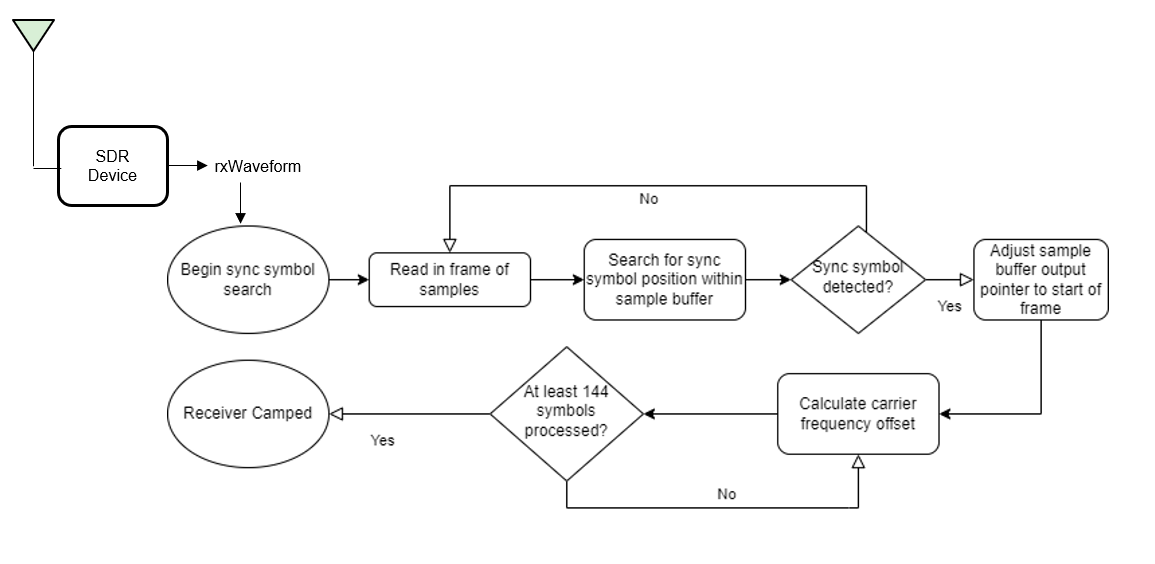

### Receiver Processing

This process is the reverse of the process that happens at the transmitter.

#### Channel Estimation and Equalization

Initially, the OFDM receiver performs channel estimation on the OFDM demodulated reference symbols. To remove the effects of time-varying fading, the receiver selects two reference symbols from adjacent frames to estimate the channel at two different points in time. The receiver then linearly interpolates the channel estimates between the two reference symbols to get the channel estimates for the header and data symbols. The `ofdmEqualize` function then equalizes the reference symbols and data symbols using the channel estimates.

#### Header Decoding

The receiver extracts and decodes the header symbols to get the data symbol parameters such as FFT length, subcarrier modulation scheme, and code rate. The receiver uses these parameters to demodulate and decode the data symbols.

#### Data Decoding

The common phase error (CPE) affects all subcarriers equally and the OFDM receiver uses the pilot symbols within the data symbols to estimate CPE. The `helperOFDMRx` function corrects the phase errors in the data symbols and the `qamdemod` function soft decodes the data subcarriers into log likelihood ratios (LLRs).

The receiver then deinterleaves the demodulated bitstream and the `vitdec` function performs maximum likelihood decoding using the Viterbi algorithm. The descrambler descrambles the decoded bits, and the `comm.CRCDetector` computes the cyclic redundancy check (CRC) and compares it with the appended CRC.

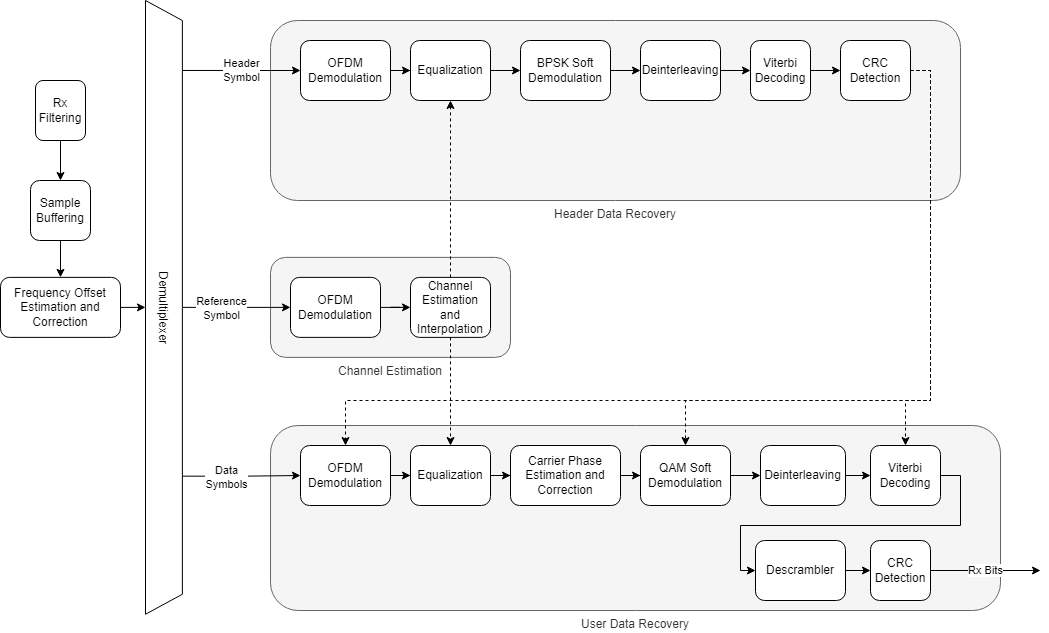

## Establishing connection to hardware. This process can take several seconds.



Sync symbol found.
Estimating carrier frequency offset .........
Receiver camped.
Detected and processing frame 10
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 1.288199e+03 Hz.
Correcting frequency offset across all samples
Modulation: 256QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 10: @aDmmas.rdf 8D□<T#`Wo2L$) hell/q_gp<d!□I|$,/ WEsl □0@!L$u W^S □0(L-dl/`Ww2,e)aH$| k!wkPdl!@Idh□n(□Os|,!0H!Lm□ S-{l□!(□□<l/@W□2.%9 (%|(/ _/0,l!@Hmh□.`□op| □□@!D}m`□>V,□□)L-=l+ Unv$u `*gl,
□G#Rld!!Hl □.(□K!|$□`@!fdu`q□{` 0(□%,|c`v□r□e` x"| □0_op|$!aHdd□.(□M%$$□□@!d,m S□{$b `□□□l' g□R,-9`(&|$	0GgPld!!H|dd-`□oad □ @%D-o`3*[`□□(□'>,/@Vo□□u``J7l`- ]/r-$!aHl □:(□M#l □1@ L□m`□~s`□□8□□-l! vw>$,! □$t □□].P<l# H<$□m`□MQt □`@ L4l`q
Sd 0` □<t# BU□`<8`
□|(
 Vcp=l!AX$,□. □ma| □ @ b/g s□B`□  □□$t# ve6□4!`□<T$□0Ec0?|!!H4 □□%□T □`@ F□u`□kC  0x #□l# CU2□□9`82l □ G&P%$ @xd  >□□#PD □ @`D□w`□9N □ □□|% &□2□&  □□t □ MbP<|!`X4 □□□□O`t □□@ b□|`□□K`  h □□D!□Gur □h□\ □ Dcp□l □(T □:`□□pd □ @!J,}`q	[`  8 □<l"@p}v□□h *□T$□ EbP□T □□<,□x8
m t □ @  %| Q□Y, 08 □
|" QTv %` Z□| 
 Dc0□d! (4  □(□k□, □ @ `□l □XR □ 8 □;|"@at: □  □
D 	 EcP-D!@x|  :8□E0l □ @  =}`□?G`    □?□"`BU~ □( 
□t8□`Gc□□|  h$  
86C□D □ @ &
U`A`  ` □□\" 1]2 □` 
□l □ D#P□□"<  □0□A`D □P@  .'!C     □□D A□LV 
    D □ D"P
l!`□$  □8□Cq|

Detected and processing frame 11
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 1.289982e+03 Hz.
Correcting frequency offset across all samples
Modulation: 256QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 11: @-Fme!q.Zd$` □
,|c`W□□$$ `.u|$□ _#0<d @Hel$-(□mrll□ @!D,o,Wzr □□8□m-d% W□2$e) 8l|$□0E&Ro|! H$ □90□mbt$□p@!Lo|!q=S(□ `□#,t# FwR□,!`□e|(□`^cp=d!AHlh□/ □Eqt □□@aD.}`□.S`.□ D□tl- Wwv,4`$\,□0O/P,|!`Hd □k`□Mr|l□P@%F-e Q?Sd□`( □,t' F}2"$ 5t □0G!□□l%AxT$□* □m0\$□ @ L4} 3□z`□ 8 □,l/ V□vl5!5T,□0G"04| ax< □□K t □ @ Dttaq
Sd □ Lc5|#□Vw>□& g|,□ GcP□d!aXl,□m`3C`t$□ @ F,t □+R □□( □
|#`Qu:□da`x4L8□ E#p□$! H□ □*(□Cp| □0@  -\aQ=s$ □`□□4|# WU□ , 'd$□`_cp
<! xl □: □O1T$□ @ d$| 1□r     □=T# u□* □8`*□t,□□E&P□l!aH, □k(□G□T □ @ @□l □;B`  □□t#`BU6 =(□| □ Ebp-l!`Hd  	8□e`T □ @!d?l □□B   0 □□|!`vWz 5i □□\ □ D"□=|!aX□h□□'p| □p@  □u □>K   P □□L#□G□2 ?! □□T □0G"P□l □(\, o8□a D □ @ l=u 1□C`□ (□□$t"`q\>□l  □cL 
 D"□□$ aH$$□+(□m0\ □ @ `□| □□Yh  p □□D#`C~~ □8 □□| □`B!0□| `8\, □(□□□, □ @ L □hG`□ !□D" Pt> □(`□□D8□ D"□□D □□d □□o0\  @X  o| □□s`  X □□T"□V|v  □□\8□pGcp□d, ht  	0> @D(□□A`□-L y   0 □
l#@ G* &  □□l □ D"□
$#4 □□ □□□D □Px  TT#1	C   x □□D a□]R -0  □\ □ D"□□l `Ht, &A T □0C  □$ □□F`    □□T

Detected and processing frame 12
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 1.290838e+03 Hz.
Correcting frequency offset across all samples
Modulation: 256QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 12: H!d-m w>{h□0 Hemd' Uov□u# X%l$m woRld! Xdd&n ^o#d$! X%dlu wm{h&0`XMmmc`r□v <(`xwt,k0Fk0$,! H%hf. _ost □ @e,to`□*rd□0 □#/d#`wfr□d!`8dl,o0_'plda H$`djh□/st □0Aanm□ soR`$□(□Gll/ vwr$$#`H'l,□ MkP4,!!X,d,o(□M1d □0X Bde`q+[l□ h□□$t'!FwV&,)aH$l □`_grmd Ax|$$- □/qT □0@ D=□ sor &0` '=|/ f□v,d!`($d □ L"□□|!@H$ □j8□Ms| □□H F,g 7?C` 0`□#-d# Rur□□( 8□| 
0]#p=$ AH|$□: □gSt □ @ B□□ □+A □□( □□t"@sW6□, `h7| □ FbP-d! Xd □□`□G`d □□@!d4e`□□Bd□  □□□T# cmR□□8 □□T$
0F#p□l!`x< □j(□epl □ @!f-U 1□X`   □□?t"`Ro□□4 `
□\ □□M#P□l @hT □□0□
□l □□@ `-| □:B` □` □ll#`F□r 7(`*3l □ E"p}l! Xd □□`
#`| □ @!F<\ □	I     □
d' fw> e)`□3| □ E.P/d!aHd □9 □O□l □ @ `=T`□□K   □ □□T!Awm□ <  
"l □ EbP*$ □x|  □(2!0$ □0@ F□d`W:B   □ □=l"@SU□ □( □0$ □ D"P□d!Ah, □□(□a l □ @ $
l!Q□@$ 0
□D"` o.□o( 
□t □ E#p□t!@8T □□ □O < □ @ "□|`□xo □ 8 □
L#`□\2 □( □
D 	 D"□□\  hL  □□□G0l □ @  =e`□+B  □x □□<" c%v □0 □□D 	pGc0
l @h$ 8
  D,□ A`L
T`□
@   ` □□l#@2M. □a`
□t □ D"□□$#| □□□□\ □P@  □t B   ( □□D □□DR □8  □D □ D"P□d! x$  
□>!

Detected and processing frame 13
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 1.291657e+03 Hz.
Correcting frequency offset across all samples
Modulation: 256QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 13: @ fle$Qm{`□0h□□$t#`vo6.<!`
□l8kPG'0,d! H$$$l`□mr| □ @!L<g □n^$,□`□g,t' Wor"dc`x%|$□0_#p-$!`X|,□/`□Mc|8□PH □4□ □ZR,□0 □ae|# w}6d% %|$/0]#0<d!`Hmd□>8□DAt$□ @!l4} Q/[`□0`□□-l# wo~"%)`j'd /0O/P-|! h$d".`□M!| □ @!L,} s>S " `□
%T#□V}2□□aaZgl □ GbPld axuh□+ □'ql □0@!N<l`1
K`□0  □□l- g□v□□``□gd 
□E#pl|!Ax,(□
 □C0$ □ H!B4w □□[ □ `□□||"@'□2□d `hw| 
□E&Pld !x|,□: □K!$ □0@ F:ud□Z~`□ 0 □
t#`swv $8 h5D(□ Db0,$!@X, □:8
a t □ @!D□l 1
Yd  ` □-|#`FvR □□ □e|,	`M#P□,! x< □: □Gp| □ A L□U`1□J` 0`□!%$# sUv□□ □L □ Dbp
|!`x$ □8(2□cL$□ H @.u □□B`    □=|# F]□@□` □6| □ E"0-l!@xl □:(□□p\ □ @ B<T`□□C   8 □□|)`rvz□
` 
□l # D#P□$! x< □k8□-`l`□ @!l□} □□A`  ` □□D#!sLr □8□T □ GbP
d □hT  .(□□ d □ @ N,uaJ`  □ □□d" c|□□□` □1\ □ EcP□$ □X4$□98□!pt □ @  □|!q□P,  h □□t#@□T* l8 :□l 	□B#p
<!!x$ 8□□ □ □ @  □$ □xZ □ 0 □□l"@□\j □( □
D8□ D"0□D!@Xt □□G0| □@X  \t □*Z`  □ □□d"□v\^ 
8 □□D$	@F!□□t!`x,  	0>`pD8□□A`□□D`□	A  p0 □□t" gL. □+□| ! D#p44"<  □ □□pD □0@  oe`B   x □□D □□EV`
8   \ □ D"□
l! □l  z0)□ T □ @  

Detected and processing frame 14
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 1.289806e+03 Hz.
Correcting frequency offset across all samples
Modulation: 256QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 14: @ Dlm!worhf0 □□,$#`Wo2dd``Jgl$
 _gP\l! HedD. □+r|,□0@%dte s?rh&□(□'||'`Vor$<)dXdldm`UcPld! X}%D/h□-q}`a□@!l-z □;sel1(L□-mo w□6,da`Hed$%0]#pm$a Hdd□?h□Ob}d□`X &=o 1/[dd! □'ll# ro2□m `n&| 
 _c0%d!AHd`f.`□Msl`□ @!l$o`7?R`□`  c,t% V□2d□`7| % Vg0l|!`xdl□?`□MQt`□ @!D'e`□>Rd□ (□'<t+ Vo6$4a n5T 
□E#P5| aX,`□n0
M0t □0X l=□`□?K`□□`□g=$# bgR□'i`(et(
 _#p□$! Hl$$j □O"t □ @` □T`1n~ □0  □
l"@ror`%( J'\ □0G#P$□# x| "/`□E t$□0@!D
| Q?[` □( □=,#@Rm>"<(gl(+□_#P□d! xd □.(□O2l □□@!Fmea3	J  `□,t# W□r□□(4t 
□_cP
d# H<  ; □m t □ @%`/\ □□S   (□□n,fAR}R□4a`z$l □ ]np\d AX$ `□CpT □ @ f
]`□?R   8 □□t!@'w>□,c`□□| □ EfP$,!!X< □	0□M!d □ @!d,}`□□I` □X □□\#□qW^□<  
□l □□Dc0□d □xT(□n(□□`t □0@ d=d`□
F   8 □□oc@0D2□□( □□D$□ D"□□l Ah4 □> □' \ □`@  =T □□X, □x□□□L" □uz□□ □| □ DcP□l#@hl □□(□□ l □ @  □T N □ ( □□T" fo□ □( □
D 	 D"P□D D  98□Ept □P@  □T □j^   h !□l" Qu□ 
□ 8□\ □0G"p
$-, (□□0D □ @ b<\ @  `` □□|" pD2 □  □3$!A Dc□□□"4  □□ L □□@  5T`q	B   0 □□D#□□U^ 
`  □L □ D"□□d!`(l□□p< !`@ □□$ Q□B □   □

Detected and processing frame 15
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 1.291611e+03 Hz.
Correcting frequency offset across all samples
Modulation: 256QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 15: @ D<U S?Sdf -ld/ Re7F$!`je|d
 Ogp,<! H%l,o8□mrm,!0AaL$u`3?Rd&0aHoll/ Wfr,u  h&t,
 U'Rl$!"X$,□□8_ov| □ @!d,f Smr$L (D'dl/ Gg□d<(`(&l,e0^ovd$!bXmx&. □M d □ X!d=} w/Rl□ 8HEml+ vo2□u)!Xbd,M W.P-t!"H$d□:(□O□T$□0@-ll}`w/sd□ `□□?t# Fw2□oa`*fd □ G#P,l!@Xd □*h□Eqd □0@%Lm|`w/zd$0(□□□l# R□2&l)`x%l,□ M"P□d! Xd,$>(□Msm a @!F$g q□[`□ 8□c.$'`Rov□g!!jgdd- E#P<l!AXl □>(□mc$ □□@ @>} □*R □0( C□|#`R}6□ea`(4| □□LbP,d% xl $/(□oR| □`@ F□d q□Q$  '□|# U}R&□(`
□T □0G#0
d! (d`□/(□-ct □ @  ,m`S□K  p`□□□|! f□6□□!`□□\ □ E#P=l!aHd □)8□□0\ □0@ D□d □*K`  h□□$l#abwv □( □7d □ ]"p<l !Hd  .8□e@D □ @ DmW □*R`□ □ □□T! g}:□wi □□l □ ]bP□d!!H4  □□□
!u`□ @!□<u □□[  0` □□D!@G}6 □ 3T □ Ec0<4 □XT □:`□E l □`@ F}t`Q
J`  0 □5l"`GU□□□( □□t$
 Eb□□| !(□,□/(□-0l □ @  -|!q
Xd □h □□D"`#}n□=( □bl □ D"□□d! (l  	`□O0,$□ @  □U □8U □ 0 □□|#@aUz %` □□D □ D#0□D  Xt  □□□E3| □ @  
| □kw` □8@□□,"□Fur□□ □T □PE#0□d!@Xl (□!PD □ @ □,T`□8@  0` □
t"`qEr □`□$ % E#P□<"□ 8□□ L □@H  ?t C`  ` □□D!a□DR □(  □D □ D"□□$! (| 8□cp\ □`@  □t

Detected and processing frame 16
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 1.292310e+03 Hz.
Correcting frequency offset across all samples
Modulation: 256QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 16: @%&$o s/R`□0 □□-lc`WoRN,! H%d o _gPml!aHl`l/`W-bd □0@!D-g`3nz □0h □<l+ V□>□$a .4|,□ M"P,l# X%`,/(□Ms| □ H!l□}`□*C`,0( 'll/ su6□/) .%t(	`_"p=|! Xld□>(□mqT$□□@ Bmo`w:S`$! □□-l' bm2"%h ,%T □ W#0ld! xl □+(□Mqt □P@ F□|`q?Z   □,d!□Wo6□d `(7| % Vc0/d%@H$l□j(□E | □ @!dl□ 1.s   □ □□d/ vo>□'h`x□t /□Eb0□l ax,,□> □mq| □0H!L||aq?J` 0□4l#AV}:□dh (g| □ E"P<,!AXl(□o(□ept □ @!L.U`□kj □   □□d"@Vo>□e! 85| □ EbP□d#`x4  
x□CPd □ @ `□t`q□Rl 0`□□□|# Rmr□-0 
□|(□ Ebp□,!`Xl □> 3-!| □ @ l=} Q9O` □`□□4t/`3U. □1`□5|$□ E"P□|!AH,  
(□M□\ □`H @□$ □+J   □?|# PUr□>  □ l □ D&□,| AH,  □`□K`L □ @`@-t □)[`    □
t!@g□z□6`□T □ Efp/|!@X< □80□Cp]`□p@!&□l`□>I     □□D! R}> □(□t □□D#p
t □(T,□k(□□`L □□@ n,} □>R`  8 □□|" "O□□□h □□L □ D"□□| □h< 
)0□g D □0@  >l Q□Yh  p□□□D# □mR □( □□t □ E#p□t @hl  
(□□ d □ @  □d □hG`□ □ □5T#`2t> □h`□
D<□ D"□□D □8d  □m□t □p@  
d □□G` `  □
l"!v\6 □□ □□D8□pFc0
l  Ht  9(2APD(□□A`d□| H `p8 □□d#`6W□ □  □□| □ Dap□□"4□□ T □PH  4d @`    □□D a□DZ =    | □ \"p□$!@xd 0:A L □□@  □d!q□G

Detected and processing frame 17
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 1.292386e+03 Hz.
Correcting frequency offset across all samples
Modulation: 256QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 17: Ye.lo Un{h&08Dg,$obVn2ld) HwmmI□W*P,$%#Im$&>(□osll□ Xa,lo!Ums(B E$$' w□Rf< `hglxo0_gp,<' H-dF-`□kbl !□X!L|gaWo{l$0(□gmd' rnrdd!`Jgm`m0U/Rm$!AXm$□n`□Krmd#a@aL,}`w>R$n!`Lg4do@Gwv$,#`(5|(o0O/p,$!!He`l□ □or| a0@!fge`Q□q( p(□□-d# voR□□a h5$ □`]/2-d! xdl□o(7-"| □ @!F□m!S.S`"0`□%,l' gg□l,8`j$\ □ EbP=|!`X$,
?`□Gql □0@!L=}`□/Rd □□,tc Bw2□%( 
'|$□ EbP<l!`H$ ,.8□EST □ @!D
m □□K,&□ □□e|#@am~,$( *□l □□G"p,d% X< □:h□Oal □ @!L=l`q□K`"□(□□4T# V}V □` 
□t 
`ObP5d! h,$□+ □o0| □ @ L□u`q?Z`□  □□dl#`boR 7``x□T 
 Vc0□l!@H,$□+(□O□d □0@ `4| □:r`  ` □,$# Rm2 4 `x□T,□□GbpL|!!Hl  
 
# | □ @ F?\ □□S   8 □□|# W}>□,( □fd □□Gc0,,!□Hd  □8□E□d □ @  □U`□:[   8 □
d#!VW2□5h"l □ G#□□d □xT, Z02□ l □ @ $□o □□F   □□T/@2O*□□  □□\ 
 D"p□| ah< □□ □g | □0@  <d □□K` □h□□□L"`□}n ,8 *□t 
 G#0□<!T$ 
`□%□< □ @  □T □(^`□ (□□)T#`□\v □  □□D □ D"□□l  □\  	0□M`| □□@  -|`□
K`  P □
l" aTR □( □□D$□0E"P□,  Xt (.□ D □ @ L□D □□@   8 □□t" p}r □#`□'| □ D"0□□"d 8
□0| □0@ □□L Y     □□D#a□Tz 4  D □ D"□□d!`(| □?GPT □□@ □□d Q

Detected and processing frame 18
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 1.292323e+03 Hz.
Correcting frequency offset across all samples
Modulation: 256QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 18: X$dom`□-{,,` □-l|' V□6f□(`hdl,+pW#vll% Hdl$□ □mrUl□ @-L□o □.Z$,1`Lm}dy U~6ft! □□|,□`Vc□ml! Xl,□j □Mcd,□p@!N$u 7zrhF0 □cl|' Vor
'!gl$O1Wcpld!AHd|□n 2Ma| □ @!b$m 1*V$□ (□□<l#`wnr&e!aH$t$o _'p=d!AHd,$-`□k`| □ @!Lmm!S=S$ ` □□4l#AEov□"a 8'd$o□EnP%d!`H|d□n(□Oc$$□□@!l<g Wozd  `□□□l' for□5a h5t$
□E&po|!@H,(□□x□m!$ □□@ f$w □/sl□ 'l|#`G□R□$(!8gd □ E.P=d!AHld&/ □M#l$□ A`./□`□i^ □□(□□?|"`vm>&□8`□□d □ E'Pol!`X$ $o(□MRt`□□@!n□d!Q□C □0!D□<lc!fw2@□□`□□T □pG"P,|!`X4 □n`□G0d □ C f□m`1□J □ h !dt# r}v□
( □□\ □□E#P□d! x, □k02□□D □pp ">l □;B` □p□□□t#@6W2 
) 
2l □ _cP□,  H|  *`□b@D,□ @aL$T □□_`□ □ □
t=`1w:□l( 
□l 
 Db□□l!@x$ □*0□K0t □ @ F/|`□□Sh    □□D!acEr`4 □t □ G!0
, □8\( j8□□0t □ @ l□]`□
A`  8 □□l"`#w~ <8 □3\ 
 DcP□d □□□ □i8□c l □0@ `m\!Q□X   p □□|"` l6 58 
3d □ G#□
$!`h|  	(□-□$ □ @ `□$ □(n`  □ □*t"@1Nj□□( □□D,□ D"0□,!@x$  □E0d □ @  ]| 1;N`  ` □□|" RUV □  l□\8□pG#□□l! H|  ##pD0□ A  /T C` □□ □
t"` U. $3`□□t □ Db0□,"<  □ □□ T □`@  n}`B  0p 	□D □
EV □( 
□D □ D"□
$! □$ □/A0T □ @  

Detected and processing frame 19
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 1.291421e+03 Hz.
Correcting frequency offset across all samples
Modulation: 256QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 19: HeDde`qor$□□ □□llo vm2.ea`$&d )`_cv□|! He`,/ 2Mst □□@-f$e%U/zlL`(□
-|# E~vdm+ zel$m□vcPll! Xl`l? □Mat □ H!f,u □+J l0□d|#@Gw2$4iah5dd/0]"P,,!aHll□. □/VT □0@%&=□`□.[,dQ`X'll/@r□~,$!&| 
 ~cpld!aH$l,/(□oQe`□`@e&□o □*R`□0x□
e\# Rev□□)`
□| □ WgP%d  Hd$,o(□-qt □□@%F$v`1)B`□ (□□<T' W□2□,Y H4| □ Db0/t @H< □.`□O | □0H!L,} 1□Jd □` □ll# 6o2□%h 
5| □`E&P>d! Xl$□-h□Mcl □ @!l-}`1*v    □□=|#@Bg□□% 5D □ G#P,|!@Xd  >x□'□t □ @ F□|`□□Rl□□  □.$#`cmr =( 
%| □0Eb□□l!`h| □/ □O |$□ @ d4u`□+[` `x□□□T! b|> %(d|$□□_g0□$! Xd □*(□E#t □0@!`□' □9B`□ ( a-$"`CU6□% □d □ ]"□Tl!aXT  ;h□# l □□@!L6\ □□A   h 

|) rUz □`□L □ EcP-,!□H□ □98□E□t □ @#□□} □;C`  X □□t#`GU□□□!`□□| □ Ebp
d,□x\, .`□□□D □ @ f□m □□_`  8 □□|&@ Lr□□  □□t 
 D"0
,!aXl □: □C T □ @  □| q
Qd  ` □□D# □Dv□□` z□l □ E#0
d @h,  □ □□ | □ @ □
T □□@`□ ( □□T"``$□ □h □□D □ D"□□D  X|  □(□gPd  @@  4| □□^   0 a□d" !w6 □(!~□T □0G"P□,!d  □ PD □ @  /D @   0 □'T" QDr □( □□| □ B#p□□"@h$  □□0\ □ @ □□} B`  0 □□D a2MR □(  □t □ D"p□d!,  □m0, □ @  □d#1	C  

Detected and processing frame 20
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 1.289756e+03 Hz.
Correcting frequency offset across all samples
Modulation: 256QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 20: A!.4}!W>R`F□(□Em<# rg2$t)$hw|,E□Wgro|#□Hd □.8WOSl,□ @`L,o!Uo{hF□ XEtt'@F~R$| !J%|$□`_cpl<# Xm &o □/v| □□@!Lmm 1□rl&08Lm,l' U'r$l(ahglho _o0t$ @X,l□* □o#d`□0X Fmm`q
Kdb □/l/`b□r&4) Z6l □□O#pol!!x$$$.(□erl,□`H Fto S□S``! □□4lg F□2□o)`h2d □□_&Pm$ @Xmd□; W-c| □□@%B=m Sjz`$□  %,lo w□vl=)!H'| □0E"Pml!`H, &> □Oq| □□@!l□o 1/[`□ h□□-|#@q□v□□``X$|$□`E#P<l!aH|d□n8□E"| □ @ B=o 1osd□   #,l" reV□5!`j4t □ _#P□d# Xl ">x□OSl □0@!F□l`□*rh&1 □□?l#`C□> %  
□t,
 _#p
d!, □□8□Mal □ @ b4□ Q=@` 0□4t'`b}6□7h`□7\$	□]#P□|! Xl  ;(□□ T □ @!$,t 1□A    □□4d#aSW2 □8 *□t □ E"p□$!AXd` □`□g | □ @ D/U □>C`  □□t# 'V~□□9`□□d □ G#P□<! H, □9□□O0m`□ @!f□W □)Zd  ( □<t#AEW6□<h`
&| □ Dcp□4 □(T  i(2G l □p@ d□d B`    !
$"@0D□ □(□|$
 D"p□t !x4,□□8□M t □ @!@□| □
Q, 0` □□T#  %b□<  
wd 	 Dcp□d!@(, (□
□t □ @  
d □(V`□ (□□□l#@a\v□□` □□D □ D#P□D  H\  □ 
g`d □p@  □l □>z`    □	d"`A_2 □h □□D □PGcp□d  ($ h2□ D □ @ `□u`@  □ □□=T" 0D~ □` □□d ! D"0□□#$ 8□! l □`@  =t B     □□D A#T□ 
(  □D □ D"□□l! h|$ □ 7a`L □@@  □| Q
B

Detected and processing frame 21
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 1.288265e+03 Hz.
Correcting frequency offset across all samples
Modulation: 256QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 21: XeDmo!sm[`L`'m|'`vwRn$ `Hd|l+`Wgpll!!xlx□o!W/R|`□ @!D-o w{rl&  □□=|/ w~6$4) J$| □0_'P-|!@Xt`.m`WMfl`□ @!D<g`s□Sl"`□|t/ Fm6□<) jgt$-□W#P=l!`x|d$m(□MRud□ @!Do}`1nsl□ !H□ll/ voRde!`h7|,+!G#pml!AHd □>(□MsT □`H!"l}`□/R$□ 8□□t|/□Go6□$ `x't O0Wopm$! H$$□* □m2l □ @aNl} 3~R`□ ` 
<l/ Vov□'( j%l -0G&po|!AH<$d*`□Oqt a @!l|e QmS □0'<\'aG□r□, `j%l$/ E.0<l AXed&/ □□ l$□ @aD=}`□nr □□ □□□l# So6□d(`hgt 
 E.p,d#`H< □:8□Grl$□□@!B□| □>K$□0( □□|# Gu2 <□ □'l,	 G"P,l AHl □.`□o3t □ @ d.l`1	^ □ □ □□|- bwv□□9`□lT □ EcP□t!aX, □i(□e T □p@!F□|`□([ D□!=l# QU6"□  z3$ □ G#□□l @H|  □`□-P\ □ @`D□| □:C`□ 8 #□t9`&v.□$0□L □ LbP,| AH4 □(0□G T □ @ □□t`□□Z` 0P □□D#□uUv"□(`□□t,
 Dc□□$,Ah\,□*(□!`\ □ @ f=u Q□N`  8 □□d"`#u> 5 2L$□ Db□□T □X,$□+(□o D □ @ b□t!Q□Yh □p □□\"@BT> 5(`□"t □ G#p□$!AHd  : □C□l$□ @  □$ □YR`□ □ □]T" b]: □8 □□D(	 D"P
T  X$  
□□M`t □`@  lt □	F   ` □□l"AFMV □( □□t,□@FcP□|  (d □□,PD4□□A`□□t □	C  `` !□d"`q]> 4!`□%d □ D"□
<!`□□ □□ □A0D □0P  o}#C   h □□D !□MV □(   D □ \"□□|! (,$ 	07C`t □@@

Detected and processing frame 22
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 1.288637e+03 Hz.
Correcting frequency offset across all samples
Modulation: 256QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 22: Ac□,odU.rl&#(□□l$g`wor□ta!Hgm`M□w+Vl,!'I%aD/hWO3ld□0@`dlm W-sx, aXc,e'FgoRl□adhu|,□□_gp<,# HllDn(□-a| ! @a□do 7oSd$ 8□c-dg@U□r$t `he|$- wbP}dc hd F>(□ovl`□!@`l-m`S?R,$□ □e-|# F□□$$!!X$l`□0Ecp<$!aH$,□j8□□c| □`H!f-} 1.r$&□  gm|g W□□&49`
'| % Oc0□l @Xl`□- □M`t`□□@ f=□ □zr □   #$l' Vw~dg9 (g|`□ ]"p<d!`Hl □> □e`| □0@ D□w □*R`   □□d|#□Fw□□&( j□t$
pE"P□l!`xd □- □Cpt □0@!D<w s/J`□ ( □□t"@Bov□$ !H□t % G#P,$#□H$ □>h□e`| □ H fn}`□□Zd 0□<t"@&|~□&  z6|$/0O#p□$! (,  :(□O t □ @!N$m`q□C`□ `□□$t#@G}>□□ `□□| 	 OcP
d!`xT  + □% d □□@ f4T □□R`□ □md"@v}2□$` □□l □0D"P}l# H<  *(□-0t □□@ F,T □□K  □h□□□l# r}2 □!`□□| □0Ocp□$# X<  : □G!T □ @!@□% □	Z   h□□□\#!Cur□5  □7l □ D"P□d aXt(□/ >A L □□@ D□%`□□G`  8 □□t#`□]. □  
□t □ D"□□T !h, □+(□G t □ @ □□d □
[` 0x□□□D#`2m* =( □□t □□G#p□l!`X|  □`□A0l □ @  □T □xN`□ 0 □>\"`PL□□□  □□D □□Db0	T  h\  	8□mpd □0@  
}`□
A  0h □
|" #|□ □0 □□D □ F#P
d  H$  
`□□pL □ @ d□t`□8@   p □□l" □]z □h □□l □ Dbp□□#|  □□ T □0@  =T □□A   □
D!!wT> 
( □□t □ D"□□$#`□d□□□l □

Detected and processing frame 23
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 1.290045e+03 Hz.
Correcting frequency offset across all samples
Modulation: 256QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 23: @a,me Smzlf mo|'□Vg6n7(`hgl ' woR\d!□Xll□o □Ea| # @!ll□`q_s`d e|l# Vw□,$# h%|,/aVg0ll! x|`$o`□MR| □□@!,%~`uor,□0 Le□|'`go6□%! h'|(m□wcP$d!aXel□: □Oqt □ X!ll} □:Slb0hL□□tg BvV□4  Xgd$+ OcP-| @x,l$?(□Ka|$□0@!l□}`Q□Rd  (□'%|c W□v□$) h'd /□W+pll!`Hd □>`□Ycl □0@!Fmo □>Zd□0h □<d; vg□,d(`~□|$□ Gcp<$!AXd$&> □o&| □ @!,<| □>[ □ 8D!=<#`v□6□,` N□$ 	`WcP$$!AXl □*`□e#l □□@ $<md□{V □0( □?t& fw>□4``□□d 
 Ec0,<! X$ □+(□%#t □□@ L5maQ□Y$□` □□□T!□RwV □8 □□t,□ U#p
l!AX, &/(
MPT □ @!F□o!Q□[`□ ` □mt'`C}*□□` □<T,□□E#P□| @X,  h □g \$□□H!F□\`1□B □ h !oT# fW2 □a □□, □ E"0
d `X$ □9(□MPL □ @!f$\ □;B`  □ □□T' R□2□5 □l □ O"P%d!`Xd  □ 
e $ □ @ D=|`□□S`  □□t#□Gu□□□  □□| □ Da□□l □8t  .(
□ | □ @ F□|`□	C   □ □□d"`□nv □` □'L □ Eb0
t □h<,□:(□a $ □ @  □| q□H( □`□□□t#``t2 □8 *"| □ F#0
$# Xl  □(□c l □ @ □□$ □8v`□ 0 □□l#`3\b □0 □□D(□ Ebp?D `Hl  □0□G`| □ @  □U`□8^   ` □	d"□QU6 □8 
□t □pF#□□d  HT 8/A0D,□ @  □T @`  ( □□|" 1|& □` 
□| □ D"p□□"□  □ □□ | □`H  ?w`B   p □□D A□EZ □(  □D □ D"□
l! □$ □□a T □ @  

Detected and processing frame 24
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 1.289751e+03 Hz.
Correcting frequency offset across all samples
Modulation: 256QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 24: @!d,o`s/rd□□`□□m}c`gnrDt!`□7d`/!_'Pul%`xd lm`□+cl □0@-&tg s/r,d08□#,dg Wgv$<!`.dd$e□Mcp-d!@HtlNm □mat`□ @!ll□ □*Z`f□□,lc Em□□e!`Hg|,k□]'r,d! xlld. □Erld□□@!f<u`w}S$$#`Hc||+`SnR□4a`z□l 
0O#0%d!aH$,$?h□mS| □`H!F=□ □.{`" `□c,|' W}2&□``
□| %0O/Pe|!@(d$□?(Zmp| □ @!$4o 1nC □ □et' '□r□□x nw| □ O"P=d!AH, □□8□mq|$□ H!N}} Q?J` 0 @el|#`Fm2□&  Xg|$□`FfP,l!AXl(□n`3M1l ! @ `□t 1□v □□8 □
t#@v□r&e( n□T 
□O#pl<!□X,  □ □G`|$□0@ $□|`q□Y$□□`□
□,#`Vo6□<(`□5d □`E"P□d!`Hl □j □O□|$□ @ Fle`□□z  □□□|# vuz□□05|8□ OnP□l! H$ □?`□E | □0@ @=| □
K □□`□'=d#asg6$5``l4l 
 L"0t|!AH| □□ □M!| □ @ d=T`□
J`□ 8 □□|! "}6□□ □| □ D"r=l#□X□ □;8□e□l □ @ B
~`□oY  □P □□L#`rUr$48`□□T □ E#p□$  Hl □;(□a0t □ @ ,,} O   ( □4t#@3L6□
h □!T □ D"p=, □H< □. □O□L □ @  □| 1□A$  h □□D"`□mR □9`~□l □ E#P□l! x\  □(□
 < □ @ □□l □□[`□ 8 □□|" auz □  □□D □ D"□□D □h$ □□MpT   @ □$T 1	F`  ` □□$" @uv 
0 □□\$□ Gc0□l□ 8$ 83F@D □ @ &:D C   ` □□t" #D6  0 □□l □ D#p□□"□ □	 
□□t □0@  ?T#Q□G`  □ □□D#a3u□ □8   \ □ D"□□d!@(l0 □□3M l □ A  □$

Detected and processing frame 25
------------------------------------------
Estimating carrier frequency offset ... 
Estimated carrier frequency offset is 1.289804e+03 Hz.
Correcting frequency offset across all samples
Modulation: 256QAM  and FFT Length=128
Data decoding completed
------------------------------------------


Received data in frame 25: @!j,o 3jsdf1 □g,d/bw□z,uaaHrt e□GgP-<! I-`d. SmStd□ @!Fd}`S/r,& )L%ll.@Fovlt ahf|$□ Vop$,!#K%,Do _Ob| ! @%l\g w/Rdl□1De,ui Eo6ld!`Hwd,/ _/rm$! X,dd□(W-&l □□@!D,m Qjr,Dp(H□$|o roR□$!!N%l$o0V/P-l!ax< &/`□Ecd □0@mf|m 3.r b `□□<t#`F□2n$(`j$l$-0_+p|$!aHl`□+ □OCl □ H%f,o$s^z □0 □□<l' vvv□$# J%d`□0O'p-l!`H$ □o`□Mql □0@!l=m □>J`$  □□?,'`V'v
'` *5l □ M#P/l!!Hl$□/`□M"| □ H!L□u □nZd□0  □=l#@ro6□$ `n%l □ LbP
$! (| &?`□Kstl□ @ B<m □>Rd□0`D□=l#`fe> □8 
7t,
 ]#P□d!@xd □.`□Mcl □ @ F4}!Q/K  P□$|' g}□□%( □6t □□G#0ml!`H|  .(□o t □ @ d-| □□R` □ □e/$#!Cmv □1`x6$ □ _"0|d!AXd  ;8□e`T □ @!L,W □□C   □ □
l! '~R□4 `
□d □ E#P=,! Hd □□gPt □ @#□□t`□?C$  0 □
t!□Vw6 4a`
□t □ L#p□l axt  +`□M□$ □0@!F□}`1
J`  8 □4|" cuR□□0□|$	 D"0□t!!(< □
`□o T □ @! □| Q□Kd 0x □□T" □}z□49aHfd □ D"p□d! h, □□P□□□| □ @  □e`□□F   0 □ot#@!\Z □  □□D □ D#p□T D  
(□Apd`□□@  □T □□K   ( □□□" Ut2 □( Z□D □`E#p<$  □$ h□□0D □ @ @=u`@`  x □□t"`pT: □ □t g□Gap6□#, `
□□t □ @  /U C`    □□D a L□ □   □D □ D"p
|! □d3A@| □p@ @
,#B`□

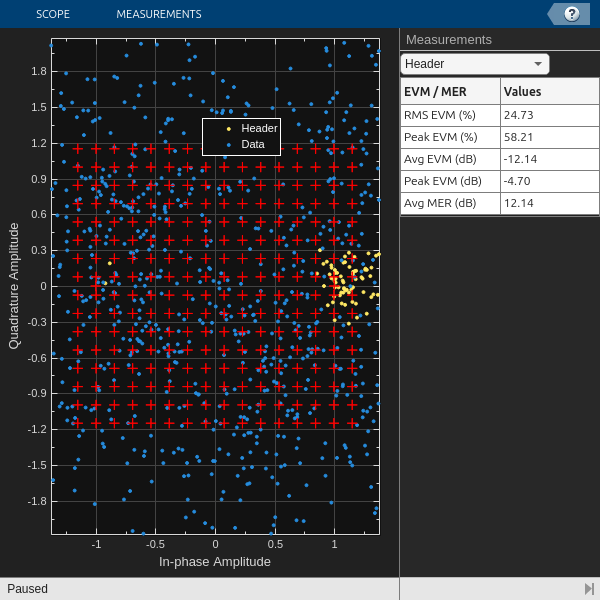

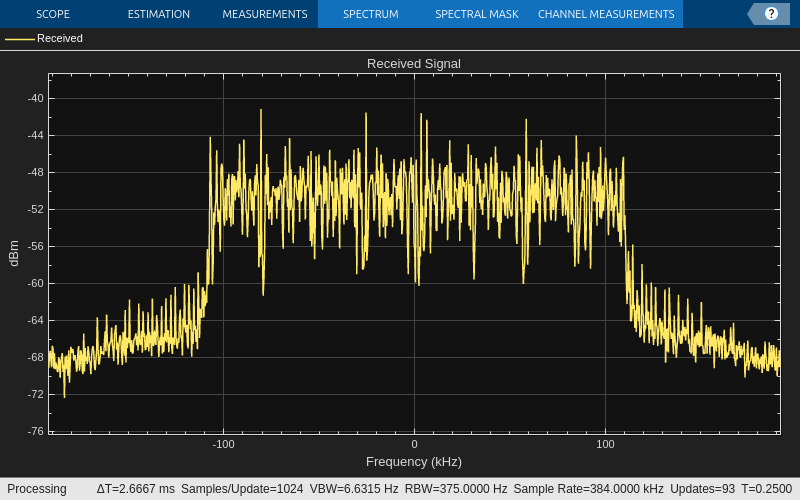

% Clear all the function data as they contain some persistent variables
clear helperOFDMRx helperOFDMRxFrontEnd helperOFDMRxSearch helperOFDMFrequencyOffset;
close all;

errorRate = comm.ErrorRate();
toverflow = 0; % Receiver overflow count
rxObj = helperOFDMRxInit(sysParam);
BER = zeros(1,dataParams.numFrames);
for frameNum = 1:dataParams.numFrames
    sysParam.frameNum = frameNum;
    [rxWaveform, ~, overflow] = radio();

    toverflow = toverflow + overflow;

    % Run the receiver front-end only when there is no overflow
    if ~overflow
        rxIn = helperOFDMRxFrontEnd(rxWaveform,sysParam,rxObj);

        % Run the receiver processing
        [rxDataBits,isConnected,toff,rxDiagnostics] = helperOFDMRx(rxIn,sysParam,rxObj);
        sysParam.timingAdvance = toff;

        % Collect bit and frame error statistics
        if isConnected
            % Continuously update the bit error rate using the |comm.ErrorRate|
            % System object
            berVals = errorRate(...
                transportBlk((1:sysParam.trBlkSize)).', ...
                rxDataBits);
            BER(frameNum) = berVals(1);
            if dataParams.printData
                % As each character in the data is encoded by 7 bits, decode the received data up to last multiples of 7
                numBitsToDecode = length(rxDataBits) - mod(length(rxDataBits),7);
                recData = char(bit2int(reshape(rxDataBits(1:numBitsToDecode),7,[]),7));
                fprintf('Received data in frame %d: %s',frameNum,recData);
            end
        end

        if isConnected && dataParams.enableScopes
            constDiag(complex(rxDiagnostics.rxConstellationHeader(:)), ...
                complex(rxDiagnostics.rxConstellationData(:)));
        end

        if dataParams.enableScopes
            spectrumAnalyze(rxWaveform);
        end
    end
end

% Display the mean BER value across all frames
fprintf('Simulation complete!\nAverage BER = %d',mean(BER))

Simulation complete!
Average BER = 2.122266e-01

### SNR ESTIMATION

%Enable properties of the spectrum analyzer
spectrumAnalyze.CursorMeasurements.Enabled = true; %enable the cursor section
spectrumAnalyze.CursorMeasurements.XLocation = [-130000, 130000]; %set the frequency range ;
spectrumAnalyze.PeakFinder.Enabled = true; %enable peak finder section
spectrumAnalyze.PeakFinder.NumPeaks = 1; %set numbers of peak you want to get
pause(3);
datas = getMeasurementsData(spectrumAnalyze);

SNRestimation = (datas.PeakFinder.Value(1)) - (datas.CursorMeasurements.Power(1));
fprintf('SNR estimated: %d\n', SNRestimation);
release(radio);